# HW 4: Multiple Comparisons

The multiple comparisons problem in statistics occurs when multiple statistical inferences are done simultaneously, which greatly increases the probability that any one inference will yield an erroneous result, by chance. A lot has been written about this problem, including:

- [Its prevalence in fMRI data analysis](https://www.sciencedirect.com/science/article/pii/S1053811912007057?via%3Dihub) (including a compelling illustration by this [prizewinning study](https://blogs.scientificamerican.com/scicurious-brain/ignobel-prize-in-neuroscience-the-dead-salmon-study/))

- [How Baysian methods can avoid the problem](http://www.stat.columbia.edu/~gelman/research/published/multiple2f.pdf).

- [General approaches for correcting for multiple comparisons](http://www.biostathandbook.com/multiplecomparisons.html).

Here we will provide some intuition for the problem using a simple thought experiment, to sensitize you to how much of a problem it can be. Consider performing the same statistical test on *N* different samples corresponding to, say, different voxels in fMRI data, using a *p*-value of $\alpha$ (typically 0.05) for each test.

Thus, for any one test, the probability of getting a Type I error (rejecting H0 when H0 is true) is $\alpha$:


$$p_{\mathrm{error}} =\alpha$$


For two tests, the probably of getting a Type I error for either test is just one minus the combined probability of not getting a Type I error from either one:


$$p_{\mathrm{error}} =1-\left(1-a\right)\left(1-a\right)$$


For *N* tests, the probably of getting a Type I error for either test is just one minus the combined probability of not getting a Type I error from any one:


$$p_{\mathrm{error}} =1-{\left(1-a\right)}^N$$


the probability of getting a Type I error under these conditions grows rapidly with *N*, implying that it becomes very, very likely that you will get a "statistically significant result" just by chance if you do enough tests:

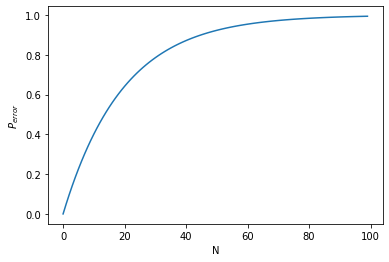

# Correcting for multiple comparisons

There are a number of different methods that can be used to [correct for this problem](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC5506159/). Below are two common methods.

## Bonferroni correction

The simplest way to correct for Type I errors (false positives) in multiple comparisons is to divide $\alpha$ by the number of comparisons, known as the [Bonferroni correction](https://mathworld.wolfram.com/BonferroniCorrection.html). This is a very conservative test that is typically used when the number of comparisons is relatively small and you want to avoid Type I errors.

## Benjamini–Hochberg procedure

Another approach is to more carefully control the false-discovery rate using the [Benjamini–Hochberg procedure](https://www.jstor.org/stable/2346101?seq=1#metadata_info_tab_contents):

1. Rank the individual *p*-values in ascending order, labeled *i*=1...*n*

2. For each *p*-value, calculate its "critical value" as (*i */*n*)*Q*, where *i* is the rank, *n* is the total number of tests, and *Q* is the false discovery rate (a percentage) that you choose (typically 0.05).

3. In your rank-ordered, original *p*-values, find the largest value that is smaller than its associated critical value; this *p*-value is the new criterion (i.e., reject H0 for all cases for which *p* ≤ this value).

# Exercise

In this exercise we will run through an example of correcting for multiple comparisons with both the Benjamini-Hochberg procedure and the more conservative Bonferroni correction.

First, simulate multiple (say, 1000) t-tests comparing two samples with equal means and standard deviations, and save the p-values. Obviously, at p<0.05 we expect that ~5% of the simulations to yield a "statistically significant" result (of rejecting the NULL hypothesis that the samples come from distributions with equal means).

Second, once you have the simulated p-values, apply both methods to address the multiple comparisons problem.

Third, set the sample 1 and sample 2 means to be 1 and 2 respectively, and re-run the exercise. What do you notice? What if you make the difference between means even greater?

% I obtained the code below from chatGPT to simulate the t-tests and save
% the p-values

% Parameters for the simulation
sampleSize = 30; % Size of each sample
numSimulations = 1000; % Number of simulations
meanValue50 = 0; % Mean for both samples
stdDeviation = 1; % Standard deviation for both samples

% Initialize an array to store the p-values
pValues = zeros(1, numSimulations);

% Perform the t-tests and store the p-values
for i = 1:numSimulations
    % Generate two random samples with the specified mean and standard deviation
    sample1 = meanValue50 + stdDeviation * randn(1, sampleSize);
    sample2 = meanValue50 + stdDeviation * randn(1, sampleSize);
    
    % Perform a two-sample t-test
    [~, pValue] = ttest2(sample1, sample2);
    
    % Store the p-value in the array
    pValues(i) = pValue;
end

% Display the first few p-values as an example
disp(['First 10 p-values: ', num2str(pValues(1:10))]);

First 10 p-values: 0.85858     0.81149      0.3983    0.064003      0.1164     0.59569     0.22626    0.079359     0.22651     0.24244


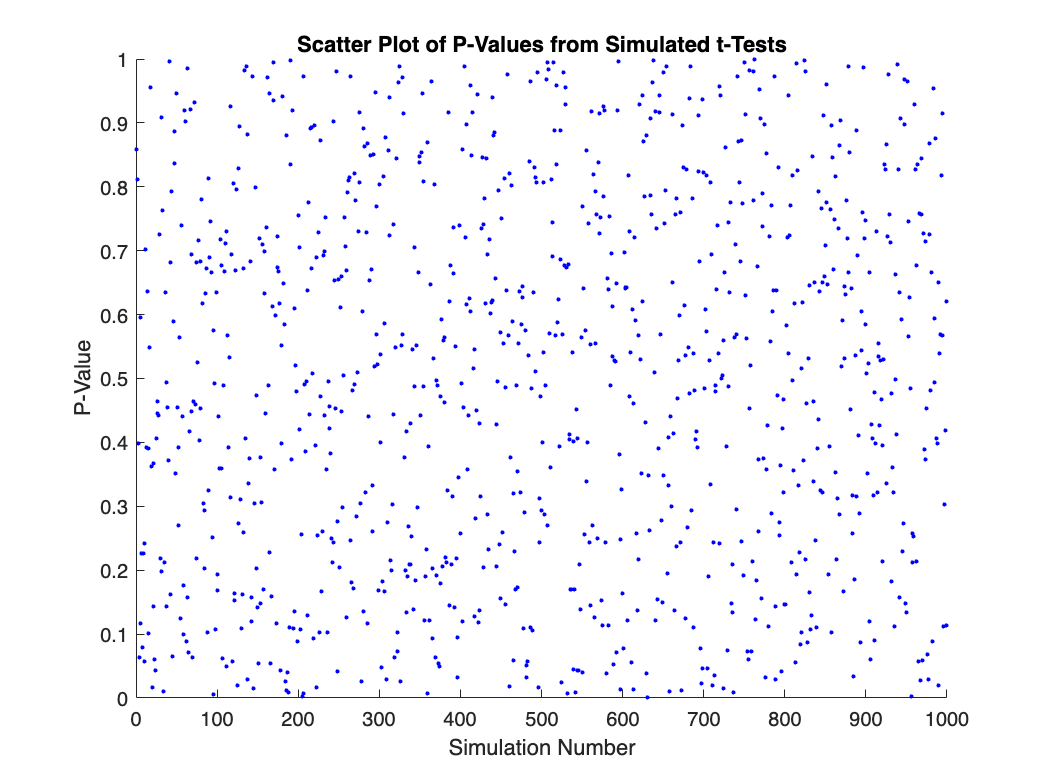


% Create a scatter plot of p-values
scatter(1:numSimulations, pValues, 'Marker', '.', 'MarkerEdgeColor', 'b');
xlabel('Simulation Number');
ylabel('P-Value');
title('Scatter Plot of P-Values from Simulated t-Tests');


% Bonferroni correction for multiple comparisons
    alpha = 0.05 % this is the desired significance level

alpha = 0.0500


    % Divide alpha by the number of comparisons
    bonferroni_alpha = alpha / numSimulations

bonferroni_alpha = 5.0000e-05


    % Find the p-values that are significant after Bonferroni correction
    significant_indices = find(pValues < bonferroni_alpha);

    % Display the Bonferroni-corrected alpha and the significant p-values
    disp(['Bonferroni-Corrected Alpha: ', num2str(bonferroni_alpha)]);

Bonferroni-Corrected Alpha: 5e-05


    disp(['Number of Significant P-Values: ', num2str(numel(significant_indices))]);

Number of Significant P-Values: 0


    disp(['Significant P-Values: ', num2str(pValues(significant_indices))]);

Significant P-Values: 


% Benjamini-Hochberg correction for multiple comparisons

    % Rank the p-values in ascending order
    ranked_pValues = sort(pValues);

    % Calculate the critical value using the Benjamini-Hochberg procedure
    numTests = numel(ranked_pValues);
    critical_value = (1:numTests) * alpha / numTests;

    % Find the largest p-value that is less than or equal to the critical value
    significant_values = find(ranked_pValues <= alpha);

    % Display the number of significant tests and their p-values
    disp(['Number of Significant Tests (alpha ', num2str(alpha), '): ', num2str(numel(significant_values))]);

Number of Significant Tests (alpha 0.05): 56


    disp(['Significant P-Values: ', num2str(ranked_pValues(significant_values))]);

Significant P-Values: 0.0014098   0.0028292   0.0028521   0.0047403   0.0063952   0.0072316   0.0076788   0.0080466    0.008347   0.0087407    0.010282    0.010813    0.011467    0.012118    0.013738    0.013886    0.014888    0.015331    0.016381     0.01662    0.017123    0.017298    0.019393    0.019855    0.020322     0.02328    0.024121    0.025747    0.026309    0.026465    0.028039    0.028736    0.029065    0.029096    0.029512    0.031403    0.031505    0.032641    0.033544    0.035618    0.037656    0.038606    0.040116    0.040376    0.041781    0.041805    0.042317    0.042617    0.042938    0.043706     0.04501     0.04635    0.046422    0.048106    0.049671     0.04977


% Adjust the means for sample 1 and 2 to 1 and 2 respectively

% Parameters for the simulation
sampleSize = 30; % Size of each sample
numSimulations = 1000; % Number of simulations
meanValue1 = 1; % Mean for sample 1
meanValue2 = 2; % Mean for sample 2
stdDeviation = 1; % Standard deviation for both samples

% Initialize an array to store the p-values
pValues_2 = zeros(1, numSimulations);

% Perform the t-tests and store the p-values
for i = 1:numSimulations
    % Generate two random samples with the specified mean and standard deviation
    sample1_mean1 = meanValue1 + stdDeviation * randn(1, sampleSize);
    sample2_mean2 = meanValue2 + stdDeviation * randn(1, sampleSize);
    
    % Perform a two-sample t-test
    [~, pValue] = ttest2(sample1_mean1, sample2_mean2);
    
    % Store the p-value in the array
    pValues_2(i) = pValue;
end

% Display the first few p-values as an example
disp(['First 10 p-values: ', num2str(pValues_2(1:10))]);

First 10 p-values: 0.00042927  8.2116e-05  1.2815e-05  0.00012799  0.00094219  0.00011414  8.6449e-05  0.00064569  3.7956e-06  0.00048996


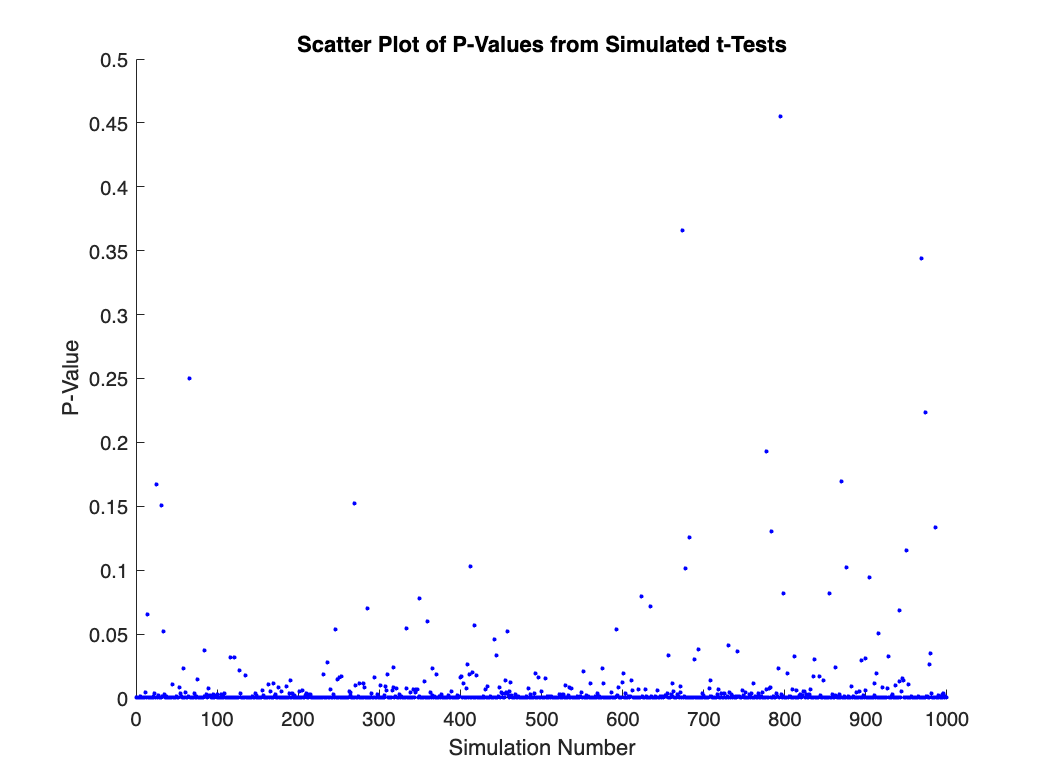


% Create a scatter plot of p-values
scatter(1:numSimulations, pValues_2, 'Marker', '.', 'MarkerEdgeColor', 'b');
xlabel('Simulation Number');
ylabel('P-Value');
title('Scatter Plot of P-Values from Simulated t-Tests');


% Adjust the means for sample 1 and 2 to have a greater difference

% Parameters for the simulation
sampleSize = 30; % Size of each sample
numSimulations = 1000; % Number of simulations
meanValue1 = 1; % Mean for sample 1
meanValue50 = 50; % Mean for sample 2
stdDeviation = 1; % Standard deviation for both samples

% Initialize an array to store the p-values
pValues_3 = zeros(1, numSimulations);

% Perform the t-tests and store the p-values
for i = 1:numSimulations
    % Generate two random samples with the specified mean and standard deviation
    sample1_mean1 = meanValue1 + stdDeviation * randn(1, sampleSize);
    sample2_mean50 = meanValue50 + stdDeviation * randn(1, sampleSize);
    
    % Perform a two-sample t-test
    [~, pValue] = ttest2(sample1_mean1, sample2_mean50);
    
    % Store the p-value in the array
    pValues_3(i) = pValue;
end

% Display the first few p-values as an example
disp(['First 10 p-values: ', num2str(pValues_3(1:10))]);

First 10 p-values: 3.1939e-81   3.786e-81  3.3176e-82  2.6518e-88  3.6894e-79  2.2159e-83  1.0444e-80  4.5279e-84   4.662e-81  1.7783e-87


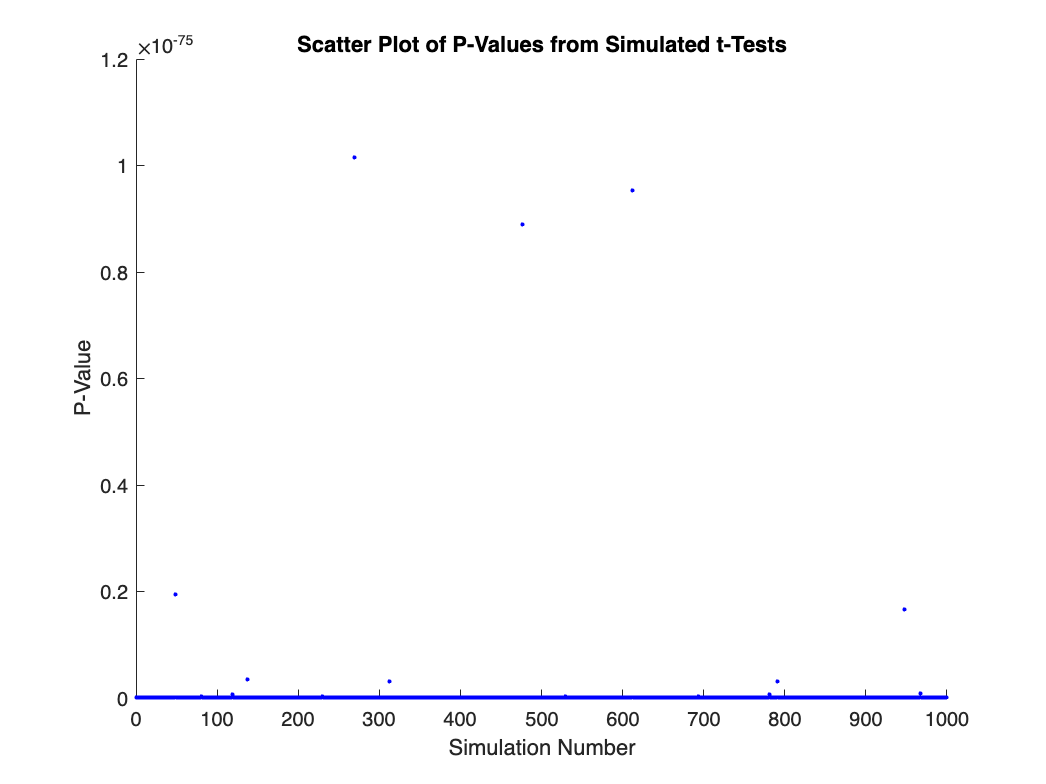


% Create a scatter plot of p-values
scatter(1:numSimulations, pValues_3, 'Marker', '.', 'MarkerEdgeColor', 'b');
xlabel('Simulation Number');
ylabel('P-Value');
title('Scatter Plot of P-Values from Simulated t-Tests');